# Acrobot Polar Tests

This script models as simple acrobot's dynamics in polar form and displays the region of your choice in $(\theta,r)$ coordinates. In particular, this shows a mesh for the region where $-\dot{\theta} > 0$, for the purpose of determining how to prove that $(\exists I)-\dot{\theta} > 0 \, \forall \theta, r \in ]0,\frac{\pi}{|\cos(\theta)|}[$

along with the mesh for $\dot{r}$ to determine whether


$$\int \limits_{-pi/2}^{pi/2} \frac{\dot{r}}{\dot{\theta}} d\theta > 0$$
 

close all;
clc;

% Set the dynamics of the robot
m = sym('m','positive'); % mass of each link
g = sym('g','positive'); % gravitational acceleration
l = sym('l','positive'); % length of the acrobot's links
I = sym('I','positive'); % scaling of the actuator
t = sym('t'); % angle in (qu,pu) plane
r = sym('r'); % radius in (qu,pu) plane

% Set the actuator symbolically
qa = atan(I*r*sin(t));

% Now define the dynamics for -theta_dot and r_dot
Irt1 = (1 + I^2*r^2*sin(t)^2);
td = Irt1*r*sin(t)^2 + m^2*g*l^3* ...
    ((1 + cos(qa))*I*sin(t) + (3+2*cos(qa))*Irt1*cos(t))* ...
    (sin(r*cos(t))*(2+cos(qa)) + cos(r*cos(t))*sin(qa));

rd = Irt1*r^2*sin(t)*cos(t) + m^2*g*l^3*r* ...
    ((1 + cos(qa))*I*cos(t) - (3+2*cos(qa))*Irt1*sin(t))* ...
    (sin(r*cos(t))*(2+cos(qa)) + cos(r*cos(t))*sin(qa));

% Set the physical dynamics of the acrobot
mass = 30; % kg
length = 1; % m
gravity = 9.81; % m/s^2
% Scaling factor for qa = atan(scale*pu)
% assuming we don't care about the eps for theta in [0,pi/2]
scale = min(0.01,sqrt(3/(10*mass^2*gravity*length^3)));

% Sub in the actual dynamics
tdf = matlabFunction(...
        subs(td, [m g l I], [mass gravity length scale]),...
        'vars', [t r]);
rdf = matlabFunction(...
        subs(rd, [m g l I], [mass gravity length scale]),...
        'vars', [t r]);
    
% Set the range of the mesh
theta_min = -pi/2; theta_max = pi/2;
r_min = 0; r_max = 100;
% Set the number of points to mesh for theta and r
tN = 1000; rN = 1000;

% Now get the mesh
[tM,rM] = ndgrid(linspace(theta_min, theta_max, tN), ...
                 linspace(r_min,r_max,rN));
tdfM = double(tdf(tM,rM) > 0);
rdfM = double(rdf(tM,rM) > 0);
% Hide the invalid region of r by setting these values to -1
tdfM(rM >= pi./abs(cos(tM))) = -1;
rdfM(rM >= pi./abs(cos(tM))) = -1;

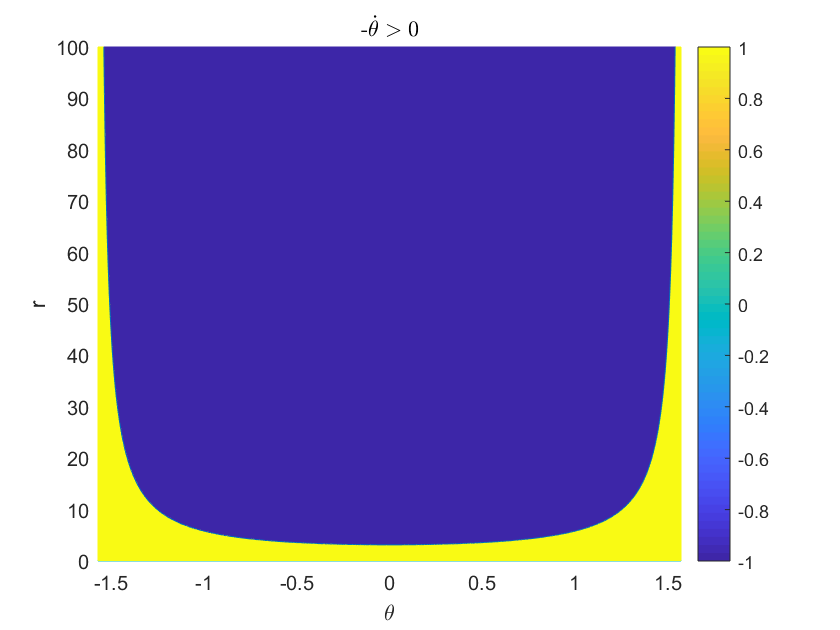

% Plot the mesh for theta_dot
figure;
mesh(tM,rM,tdfM); view(2);
colorbar;
% Display a plot of the limit for r
thetas = linspace(theta_min,theta_max,10000);
hold on; 
plot3(thetas,pi./abs(cos(thetas)), ones(size(thetas))); 
axis([theta_min,theta_max,r_min,r_max]);
hold off;
xlabel('\theta');
ylabel('r');
title('-$\dot{\theta} > 0$','Interpreter','latex');


% Check if any of the  dynamics within some range are <= 0.
% Note that we simply have to check the bottom of the range == 0, 
% since anything outside the pi/abs(cos(tM)) is equal to -1.
any(tdfM(pi./(6*abs(cos(tM))) < rM) == 0)

ans = logical
   1


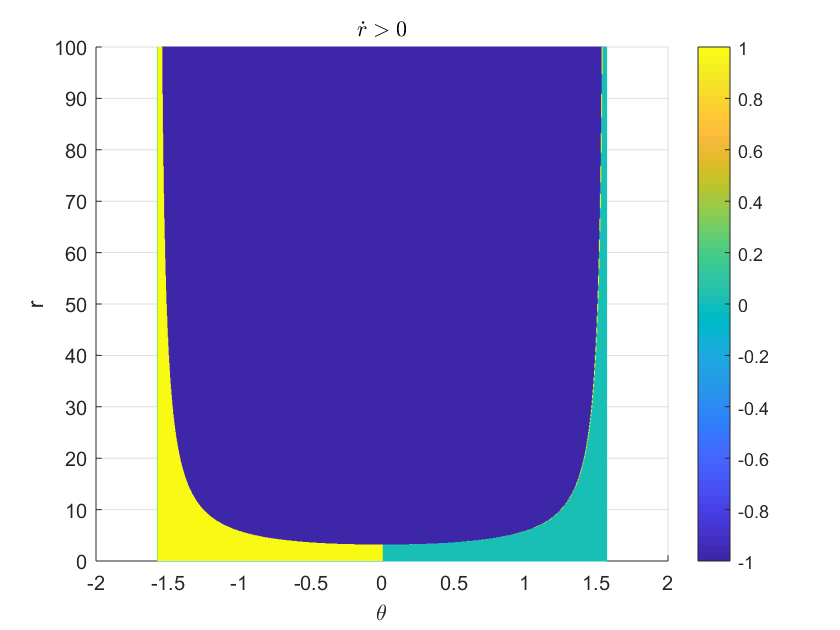

% Plot the mesh for r_dot
figure;
mesh(tM,rM,rdfM); view(2);
colorbar;
xlabel('\theta');
ylabel('r');
title('$\dot{r} > 0$','Interpreter','latex');

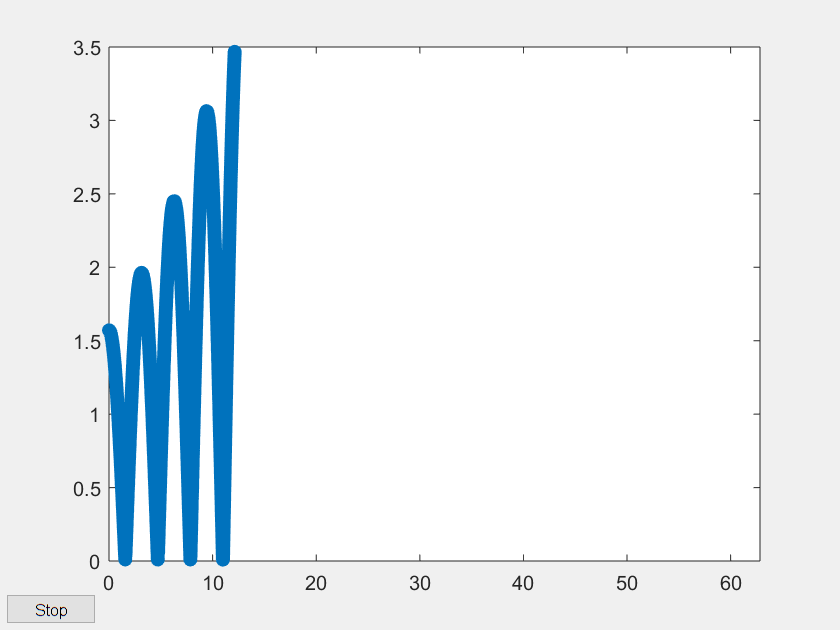

Error using odeplot (line 65)
Error updating the ODEPLOT window. Solution data may have been corrupted. Operation terminated by user

Error in ode45 (line 491)
        stop = feval(outputFcn,tout_new,yout_new(outputs,:),'',outputArgs{:});

% Integrate rhat_d = rd/td, where now theta is time and 
% rhat is our new state r(t(theta))
rtd = rd/td;
rtdf = matlabFunction(...
    subs(rtd,[m g l I],[mass gravity length scale]),...
    'vars',[t r]);
% Plot this across a few intervals of theta (from 0 to 2*pi)
T = 10; % number of theta time intervals
r0 = 2*pi/4; % Initial angle at which we start the pendulum
figure;
ode45(rtdf,[0 2*pi*T], r0,...
    odeset('AbsTol',10e-14,'RelTol',10e-14));